# Step 1: Data Preparation and Choosing Sensor

clc; 
clear; 
close all;

%importing of the Training Txt file 
engine1 = load("train_FD001.txt");

vars =["unit number","time in cycles","op setting 1","op setting 2","op setting 3","sensor measurement 1","sensor measurement 2","sensor measurement 3","sensor measurement 4","sensor measurement5","sensor measurement 6","sensor measurement 7","sensor measurement 8","sensor measurement 9","sensor measurement 10","sensor measurement 11","sensor measurement 12","sensor measurement 13","sensor measurement 14","sensor measurement 15","sensor measurement 16","sensor measurement 17","sensor_measurement 18","sensor measurement 19","sensor measurement 20","sensor measurement 21"];

%checking for the missing values

missing_values = max(sum(ismissing(engine1)));
missing_values% there are no missing values

missing_values = 0

% changed the array to a table
engine1Table = array2table(engine1, 'VariableNames', vars);
engine1Table

engine1Table = 20631×26 table
    unit number    time in cycles    op setting 1    op setting 2    op setting 3    sensor measurement 1    sensor measurement 2    sensor measurement 3    sensor measurement 4    sensor measurement5    sensor measurement 6    sensor measurement 7    sensor measurement 8    sensor measurement 9    sensor measurement 10    sensor measurement 11    sensor measurement 12    sensor measurement 13    sensor measurement 14    sensor measurement 15    sensor measurement 16    sensor measurement 17    sensor_measurement 18    sensor measurement 19    sens

%since am using livescript, the summary function displays the summary quite
%well..and this can change 
summary(engine1Table)

Variables:

    unit number: 20631×1 double

        Values:

            Min           1   
            Median       52   
            Max         100   

    time in cycles: 20631×1 double

        Values:

            Min           1   
            Median      104   
            Max         362   

    op setting 1: 20631×1 double

        Values:

            Min       -0.0087 
            Median          0 
            Max        0.0087 

    op setting 2: 20631×1 double

        Values:

            Min       -0.0006 
            Median          0 
            Max        0.0006 

    op setting 3: 20631×1 double

        Values:

            Min         100   
            Median      100   
            Max         100   

    sensor measurement 1: 20631×1 double

        Values:

            Min        518.67 
            Median     518.67 
            Max        518.67 

    

%summary

% for purposes of syncronizing, i have put most of the summary output in a
% table
for i = 1:length(engine1(1,:))
    Count(i) = nnz(~isnan(engine1(:,i)));
    Mean(i)  = mean(engine1(:,i));
    St.dev(i)    = std(engine1(:,i));
    Min(i)   = min(engine1(:,i));
    P25(i)   = prctile(engine1(:,i), 25);
    P50(i)   = prctile(engine1(:,i), 50);
    P75(i)   = prctile(engine1(:,i), 75);
    Max(i)   = max(engine1(:,i));
end

DataSummary     = table(Count', Mean', St.dev', Min', P25', P50', P75', Max', 'VariableNames', {'Count', 'Mean', 'St.dev', 'Min', 'P25', 'P50', 'P75', 'Max'}, ...
    'RowNames',vars)

DataSummary = 26×8 table
                             Count       Mean          St.dev        Min        P25       P50       P75       Max  
                             _____    ___________    __________    _______    _______    ______    ______    ______

    unit number              20631         51.507        29.228          1         26        52        77       100
    time in cycles           20631         108.81        68.881          1         52       104       156       362
    op setting 1             20631    -8.8701e-06     0.0021873    -0.0087    -0.0015         0    0.0015    0.0087
    op setting 2             20631     2.3508e-06    0

%visualize

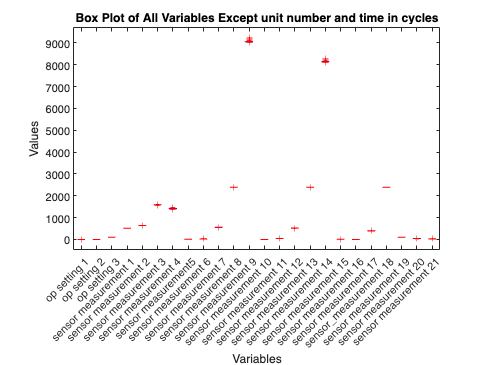


% box plot for all variables except unit_number and time_in_cycles
figure;
boxplot(engine1Table{:, 3:end}); % Excluding the first two columns
xlabel('Variables');
ylabel('Values');
title('Box Plot of All Variables Except unit number and time in cycles');
xticklabels(vars(3:end)); % Label x-axis with variable names
xtickangle(45); % for better readability

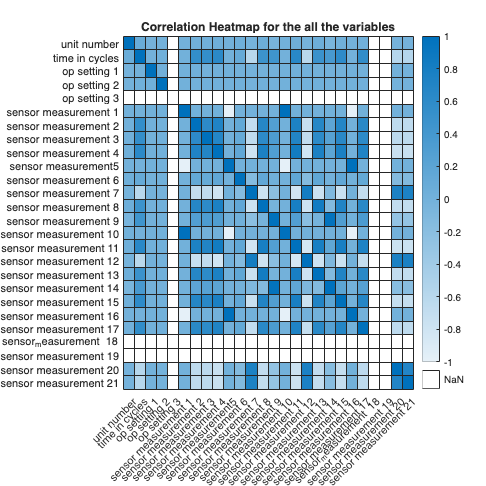


correlation = corr(engine1);

h = heatmap(correlation, 'MissingDataColor', 'w');
labels = vars;
h.XDisplayLabels = labels;
h.YDisplayLabels = labels;
title('Correlation Heatmap for the all the variables');
set(gcf, 'Position', [100, 100, 800, 800]);

% Choosing sensor 11 due to following reason

- Less Correlation: Sensor 11 is less correlated with other sensors, making it a good choice for an independent predictive feature.

- High Variation: The distribution of sensor 11 shows good variation, which is essential for predictive modeling.

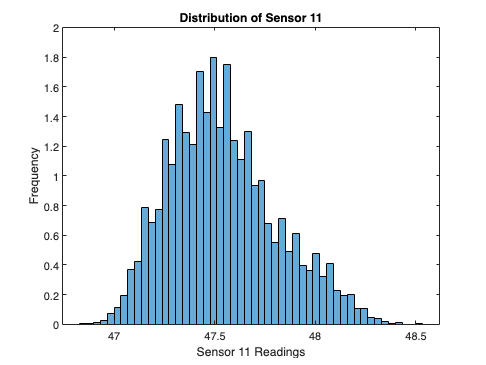

% Plotting the distribution of sensor 11
figure;
histogram(engine1Table.("sensor measurement 11"), 50, 'Normalization', 'pdf'); % 'pdf' for density
xlabel('Sensor 11 Readings');
ylabel('Frequency');
title('Distribution of Sensor 11');

%  Calibration, Validation, and Test partitions:

% Exclude sensor 11 from data matrix
X = engine1Table(:, [1:10, 12:26]);
y = engine1Table.("sensor measurement 11");

% Split data into calibration and test partitions (80:20)
cv = cvpartition(height(engine1Table), 'HoldOut', 0.2);
idxTrain = training(cv);
idxTest = test(cv);

X_cal_val = X(idxTrain, :);
X_test = X(idxTest, :);
y_cal_val = y(idxTrain, :);
y_test = y(idxTest, :);


%plot of test,train

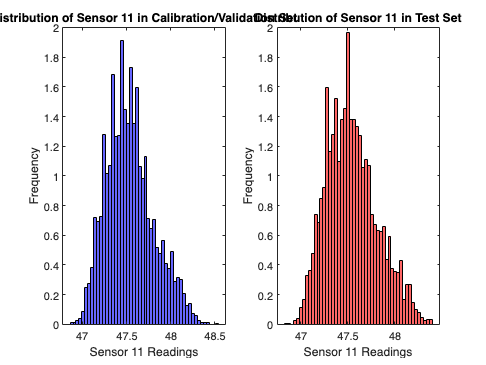

%% Plotting distributions of Sensor 11 in Calibration/Validation and Test sets

figure;

% Calibration/Validation set
subplot(1, 2, 1);
histogram(y_cal_val, 50, 'Normalization', 'pdf', 'FaceColor', 'b');
title('Distribution of Sensor 11 in Calibration/Validation Set');
xlabel('Sensor 11 Readings');
ylabel('Frequency');

% Test set
subplot(1, 2, 2);
histogram(y_test, 50, 'Normalization', 'pdf', 'FaceColor', 'r');
title('Distribution of Sensor 11 in Test Set');
xlabel('Sensor 11 Readings');
ylabel('Frequency');

## Step 2: Model calibration

% Model Calibration


% Ensure the data is in array format and double precision

X_cal_val_array = double(table2array(X_cal_val));
y_cal_val_array = double(y_cal_val);

% Initialize PLS model with 2 components
[XL, YL, Xs, Ys, beta] = plsregress(X_cal_val_array, y_cal_val_array, 2);

% Perform 5-fold cross-validation
CV = cvpartition(length(y_cal_val_array), 'KFold', 5);
mse = zeros(CV.NumTestSets,1);

for i = 1:CV.NumTestSets
    trIdx = CV.training(i);
    valIdx = CV.test(i);
    
    % Extract training and validation data using logical indices
    X_train = X_cal_val_array(trIdx, :);
    y_train = y_cal_val_array(trIdx);
    X_val = X_cal_val_array(valIdx, :);
    y_val = y_cal_val_array(valIdx);
    
    % PLS model on training data
    [XL, YL, Xs, Ys, beta] = plsregress(X_train, y_train, 2);
    
    % Prediction on validation data
    yPred = [ones(size(X_val, 1), 1) X_val] * beta;
    
    % Mean Squared Error (MSE) for each fold
    mse(i) = mean((yPred - y_val).^2);
end

% Mean and Std. Dev of cross-validation scores
cross_val_mean = mean(mse);
cross_val_std = std(mse);

% centering and scaling the calibration/validation data

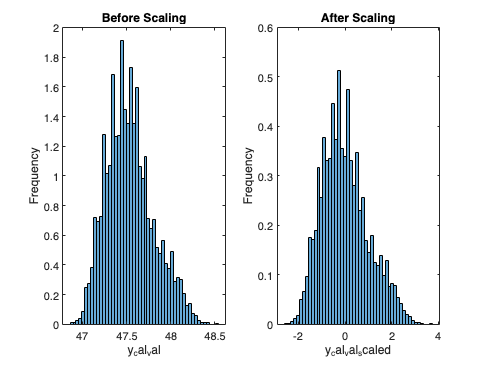

% Center and scale the X and y calibration/validation sets
X_cal_val_scaled = zscore(X_cal_val_array);
y_cal_val_scaled = zscore(y_cal_val_array);

% Plotting to visualize the scaling effect
figure;
subplot(1, 2, 1);
histogram(y_cal_val_array, 50, 'Normalization', 'pdf');
title('Before Scaling');
xlabel('y_cal_val');
ylabel('Frequency');

subplot(1, 2, 2);
histogram(y_cal_val_scaled, 50, 'Normalization', 'pdf');
title('After Scaling');
xlabel('y_cal_val_scaled');
ylabel('Frequency');

%Finalize PLS Model with Optimized Hyperparameters

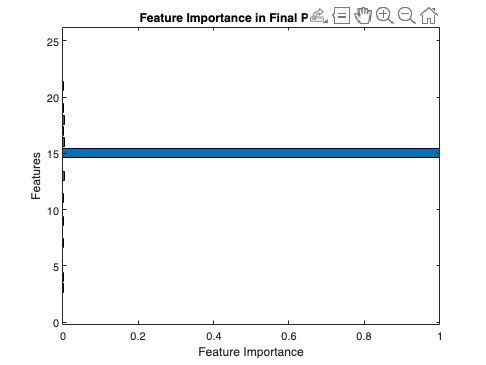

best_mse = inf;
best_components = 0;

% Hyperparameter grid
components_grid = [1, 2, 3, 4, 5, 6];

for n = components_grid
    % Initialize PLS model
    [XL, YL, Xs, Ys, beta] = plsregress(X_cal_val_scaled, y_cal_val_scaled, n);
    
    % Prediction
    yPred = [ones(size(X_cal_val_scaled, 1), 1) X_cal_val_scaled] * beta;
    
    % Mean Squared Error (MSE)
    mse = mean((yPred - y_cal_val_scaled).^2);
    
    if mse < best_mse
        best_mse = mse;
        best_components = n;
    end
end

% Fit the final model with the best components
[XL, YL, Xs, Ys, final_beta] = plsregress(X_cal_val_scaled, y_cal_val_scaled, best_components);

% Feature importance (coefficients magnitude)
feature_importance = abs(final_beta(2:end));

% Plotting feature importance
figure;
barh(feature_importance);
xlabel('Feature Importance');
ylabel('Features');
title('Feature Importance in Final PLS Model');

## Step 3: `Model Evaluation`

% Center and scale the test set using zscore

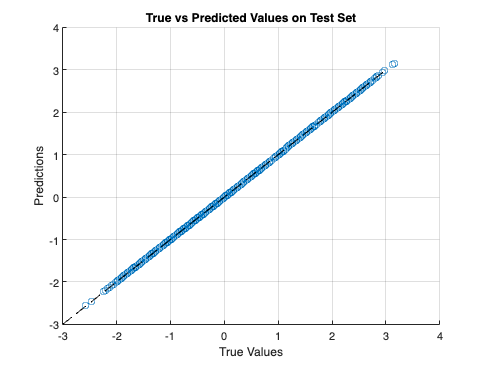


X_test_scaled = zscore(table2array(X_test));
y_test_scaled = zscore(y_test);

% Prediction on the test set
yPred_test = [ones(size(X_test_scaled, 1), 1) X_test_scaled] * final_beta;

% Mean Squared Error (MSE) on test set
mse_test = mean((yPred_test - y_test_scaled).^2);

% Plotting true vs predicted values
figure;
scatter(y_test_scaled, yPred_test);
hold on;
plot([-3, 3], [-3, 3], '--k');
xlabel('True Values');
ylabel('Predictions');
title('True vs Predicted Values on Test Set');
grid on;

% predictions and evaluating model 

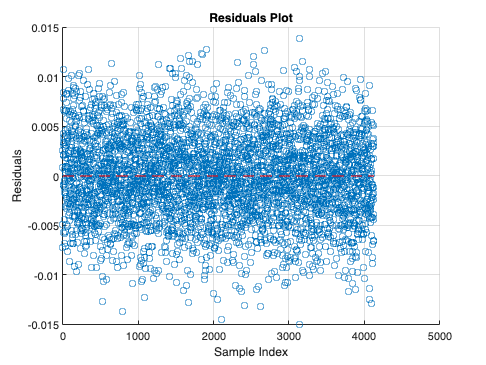

%% Step 7: Make Predictions and Evaluate Model Performance

% Make predictions with the final model on the test set
yPred_test_final = [ones(size(X_test_scaled, 1), 1) X_test_scaled] * final_beta;

% Calculate Q2_test (R-squared)
q2_test = 1 - sum((yPred_test_final - y_test_scaled).^2) / sum((y_test_scaled - mean(y_test_scaled)).^2);

% Plotting the residuals
residuals = y_test_scaled - yPred_test_final;
figure;
scatter(1:length(residuals), residuals);
hold on;
line([1, length(residuals)], [0, 0], 'Color', 'red', 'LineStyle', '--');
xlabel('Sample Index');
ylabel('Residuals');
title('Residuals Plot');
grid on;